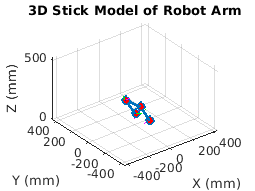

% travelTimeMS = 5000; % Defines the travel time
% travelTimeS = travelTimeMS/1000; 
% robot = Robot();
% robot.writeMotorState(true)
% 
% calculator = Lab2Step2();
% model = Model(false); 
% % angles = zeros([4,4]);
% % angles(1,:) = calculator.step2ik([80,-75,40],300);
% % angles(2,:) = calculator.step2ik([190,0,290],350);
% % angles(3,:) = calculator.step2ik([100,65,190],340);
% % angles(4,:) = calculator.step2ik([80,-75,40],300);
% % 
% % for i = 1:4
% % robot.set_joint_vars(angles(i),travelTimeMS);
% %  pause(travelTimeS);
% % end
% 
% angles = calculator.step2ik([80,-75,40],300);
% robot.set_joint_vars(angles,travelTimeMS);
% pause(travelTimeS);
% figure();
% model.plot_arm(angles)
% 
% 
% angles = calculator.step2ik([190,0,290],350);
% robot.set_joint_vars(angles,travelTimeMS);
% pause(travelTimeS);
% 
% angles = calculator.step2ik([100,65,190],340);
% robot.set_joint_vars(angles,travelTimeMS);
% pause(travelTimeS);
% 
% angles = calculator.step2ik([80,-75,40],300);
% robot.set_joint_vars(angles,travelTimeMS);
% pause(travelTimeS);

tic;
travelTimeMS = 5000; % Defines the travel time in milliseconds
travelTimeS = travelTimeMS / 1000; % Travel time in seconds
robot = Robot();
robot.writeMotorState(true);

calculator = Lab2Step2();
model = Model(false); % Assuming not connected to the actual robot for plotting purposes

% Define the points
points = [
    calculator.step2ik([80,-75,40],300);
    calculator.step2ik([190,0,290],350);
    calculator.step2ik([100,65,190],340);
    calculator.step2ik([80,-75,40],300) % Returning to the first point
];

% Initialize arrays to store the time and positions
times = [];
positions = [];

% Loop through each set of angles
for i = 1:size(points, 1)
    % Set the joint variables to move the robot
    angles = points(i, :);
    robot.set_joint_vars(angles, travelTimeMS);
  
    pause(travelTimeS); % Wait for movement to finish
    % Record the current time and end effector position
    currentTime = toc; % Assuming tic is called at the beginning of the script
    times = [times; currentTime];
    pos = model.fk(angles);
    positions = [positions; pos]; % Use the fk method to get the position
    
    % Plot the arm if needed for each position
    model.plot_arm(angles);
end

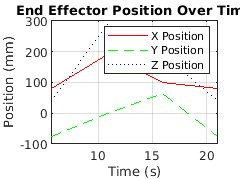


% Now we have the positions and times, we can plot them
figure;
plot(times, positions(:, 1), '-r', 'DisplayName', 'X Position'); 
hold on; % X vs Time
plot(times, positions(:, 2), '--g', 'DisplayName', 'Y Position'); % Y vs Time
plot(times, positions(:, 3), ':b', 'DisplayName', 'Z Position'); % Z vs Time
hold off;

% Label the plot
xlabel('Time (s)');
ylabel('Position (mm)');
title('End Effector Position Over Time');
legend('show'); % Show the legend
grid on; % Add a grid for easier reading